# Discrete $R_0$: $\psi(T)$, $\phi(t)$, and $\chi(t)$


$$\aleph=1+\nu \frac{I_f}{I_f + S_f}$$



$$\Psi(t)  = 1-\left[1-\left[\frac{I(t)}{M(t)}\right]^{\aleph(S(t),\, I(t))}\right]^y \\                   
 \Phi(t)= 1- \left[ \frac{S(t)-1}{S(t)} \right]^{zI(t)\left[\frac{S(t)}{N(t)}\right]^{\aleph(S(t),\, I(t))}} \\
 
\chi(t) =  z(I_f(t)/N)^\aleph$$



$$            S_f(t+1)  = S_f(t)(1-G(t))(1-\lambda) + S_q(t)\alpha + \mu (R(t)+R_j(t))\\
            S_q(t+1) = S_f(t)(1-G(t))\lambda + S_q(t)(1-\alpha)\\
            I_f(t+1) =  S_f(t)G(t) + I_f(t)(1-\gamma)(1-\theta)(1-\lambda) + I_q(t)(1-\gamma)(1-\theta)\alpha\\
            I_q(t+1)  =  I_f(t)(1-\gamma)(1-\theta)\lambda + I_q(t)(1-\gamma)(1-\theta)(1-\alpha)\\
            I_j(t+1) = (I_f(t) + I_q(t))(1-\gamma)\theta + I_j(t)(1-\gamma)\\
            R(t+1) = R(t)(1-\mu) + (I_f(t) + I_q(t))\gamma\\
            R_j(t+1) = R_j(t)(1-\mu)  + \gamma I_j(t)$$


free disease equilibrium for $R_0$ 


$$I_f = I_q = I_j = 0$$



$$S_f = \frac{\alpha}{\alpha+\lambda}N$$
 


$$S_q = \frac{\lambda}{\lambda + \alpha} N$$



$$R=0$$



$$E^* = \left(\frac{\alpha}{\alpha+\lambda}N,\,\frac{\lambda}{\lambda + \alpha} N, \, 0,\,0,\,0,\,0\right)$$



$$R_0$$


syms S_f S_q I_f I_q I_j R R_j N I
syms lambda alpha gamma theta mu nu z 
% N = S_f + S_q + I_f + I_q + I_j + R + R_j;
aleph =  1 + nu *I_f/(I_f+ S_f);

G = [1-(1-(I_f/N)^aleph)^z;                    %%Psi
     1 - ((S_f-1)/S_f)^(z*I_f*S_f/N)^aleph;  %%Phi
     z*(I_f/N)^aleph                           %%Chi
    ];

J = {};
    
for i = 1:3
    
    eqS_f = S_f*(1-G(i))*(1-lambda) + S_q*alpha + mu*R;
    eqS_q = S_f*(1-G(i))*lambda + S_q*(1-alpha);
    eqI_f = S_f*G(i) + I_f*(1-gamma)*(1-theta)*(1-lambda) + I_q*(1-gamma)*(1-theta)*alpha;
    eqI_q = I_f*(1-gamma)*(1-theta)*lambda + I_q*(1-gamma)*(1-theta)*(1-alpha);
    eqI_j = (I_f + I_q)*(1-gamma)*theta + I_j*(1-gamma);
    eqR = R*(1-mu) + (I_f + I_q + I_j)*gamma;

    J{i} = jacobian([eqI_f eqI_q eqI_j eqS_f eqS_q eqR], [I_f I_q I_j S_f S_q R]);
    J{i} = subs(J{i}, [I_f I_q I_j, R, S_f, S_q], [0, 0, 0, 0, alpha/(alpha+lambda)*N, lambda/(lambda+alpha)*N]);
%     J{i} = limit(J{i}, I, 0);
    
end

$R_0$ for $\psi(t)$

J{1} = simplify(J{1},'IgnoreAnalyticConstraints',true)

J = 1×3 cell array
    {6×6 sym}    {6×6 sym}    {6×6 sym}


F = [alpha*z/(alpha+z) alpha*(1-gamma)*(1-theta) 0;
    lambda*(1-gamma)*(1-theta) 0 0;
    theta*(1-gamma) theta*(1-gamma) 0
    ];
F = simplify(F,'IgnoreAnalyticConstraints',true,'Steps',100)

$$F = \left(\begin{array}{ccc} \frac{\alpha \,z}{\alpha +z} & \alpha \,\left(\gamma -1\right)\,\left(\theta -1\right) & 0\\ \lambda \,\left(\gamma -1\right)\,\left(\theta -1\right) & 0 & 0\\ -\theta \,\left(\gamma -1\right) & -\theta \,\left(\gamma -1\right) & 0 \end{array}\right)$$

T = [(1-gamma)*(1-lambda)*(1-theta), 0, 0;
    0, (1-alpha)*(1-gamma)*(1-theta), 0;
    0, 0, 1-gamma];

X = simplify(F*(eye(3)-T)^-1,'Steps',100)

$$X = \begin{array}{l} \left(\begin{array}{ccc} \frac{\alpha \,z}{\left(\alpha +z\right)\,\left(\gamma +\lambda -\gamma \,\lambda -\theta \,\left(\gamma +\lambda -\gamma \,\lambda -1\right)\right)} & 1-\frac{\gamma +\theta -\gamma \,\theta }{\sigma_{2}} & 0\\ 1-\frac{\gamma +\theta -\gamma \,\theta }{\sigma_{1}} & 0 & 0\\ -\frac{\theta \,\left(\gamma -1\right)}{\sigma_{1}} & -\frac{\theta \,\left(\gamma -1\right)}{\sigma_{2}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\gamma +\theta -\gamma \,\theta -\lambda \,\left(\gamma +\theta -\gamma \,\theta -1\right)\\ \sigma_{2}=\gamma +\theta -\alpha \,\left(\gamma +\theta -\gamma \,\theta -1\right)-\gamma \,\theta \end{array}$$

R_t = eig(X);

simplify(R_t,'IgnoreAnalyticConstraints',true)

$$ans = \begin{array}{l} \left(\begin{array}{c} 0\\ \frac{\alpha \,z+\gamma \,z\,\sigma_{4}+\lambda \,z\,\sigma_{4}+\theta \,z\,\sigma_{4}+\alpha \,\gamma \,\sigma_{4}+\alpha \,\lambda \,\sigma_{4}+\alpha \,\theta \,\sigma_{4}-\alpha \,\gamma \,\lambda \,\sigma_{4}-\alpha \,\gamma \,\theta \,\sigma_{4}-\alpha \,\lambda \,\theta \,\sigma_{4}-\gamma \,\lambda \,z\,\sigma_{4}-\gamma \,\theta \,z\,\sigma_{4}-\lambda \,\theta \,z\,\sigma_{4}+\sigma_{3}+\sigma_{1}}{\sigma_{2}}\\ -\frac{\gamma \,z\,\sigma_{4}-\alpha \,z+\lambda \,z\,\sigma_{4}+\theta \,z\,\sigma_{4}+\alpha \,\gamma \,\sigma_{4}+\alpha \,\lambda \,\sigma_{4}+\alpha \,\theta \,\sigma_{4}-\alpha \,\gamma \,\lambda \,\sigma_{4}-\alpha \,\gamma \,\theta \,\sigma_{4}-\alpha \,\lambda \,\theta \,\sigma_{4}-\gamma \,\lambda \,z\,\sigma_{4}-\gamma \,\theta \,z\,\sigma_{4}-\lambda \,\theta \,z\,\sigma_{4}+\sigma_{3}+\sigma_{1}}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\gamma \,\lambda \,\theta \,z\,\sigma_{4}\\ \sigma_{2}=2\,\left(\alpha +z\right)\,\sigma_{5}\\ \sigma_{3}=\alpha \,\gamma \,\lambda \,\theta \,\sigma_{4}\\ \sigma_{4}=\sqrt{\frac{\alpha^{2}\,z^{2}}{{\left(\alpha +z\right)}^{2}\,{\sigma_{5}}^{2}}+\frac{4\,\alpha \,\lambda \,{\left(\gamma -1\right)}^{2}\,{\left(\theta -1\right)}^{2}}{\left(\alpha +\gamma +\theta -\alpha \,\gamma -\alpha \,\theta -\gamma \,\theta +\alpha \,\gamma \,\theta \right)\,\sigma_{5}}}\\ \sigma_{5}=\gamma +\lambda +\theta -\gamma \,\lambda -\gamma \,\theta -\lambda \,\theta +\gamma \,\lambda \,\theta \end{array}$$

syms L
DET = simplify(det(X - L*eye(3))==0);

SOL = solve(DET, L);
% simplify(SOL(2))
simplify(SOL(3),'IgnoreAnalyticConstraints',true,"Steps",1000)

$R_0$ for $\phi(t)$

% J{2}

$R_0$ for $\chi(t)$

% J{3}

F = [S_f*z/N alpha*(1-gamma)*(1-theta) 0;
    lambda*(1-gamma)*(1-theta) 0 0;
    theta*(1-gamma) theta*(1-gamma) 0
    ];
T = [(1-gamma)*(1-lambda)*(1-theta), 0, 0;
    0, (1-alpha)*(1-gamma)*(1-theta), 0;
    0, 0, 1-gamma];

X = F*(eye(3)-T)^-1
R_t = eig(X)
g = matlabFunction(R_t,'File','R_T');

help R_T

$$X = \begin{array}{l} \left(\begin{array}{ccc} \frac{S_{f}\,z}{N\,\sigma_{1}} & \frac{\alpha \,\left(\gamma -1\right)\,\left(\theta -1\right)}{\sigma_{2}} & 0\\ \frac{\lambda \,\left(\gamma -1\right)\,\left(\theta -1\right)}{\sigma_{1}} & 0 & 0\\ -\frac{\theta \,\left(\gamma -1\right)}{\sigma_{1}} & -\frac{\theta \,\left(\gamma -1\right)}{\sigma_{2}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\gamma +\lambda +\theta -\gamma \,\lambda -\gamma \,\theta -\lambda \,\theta +\gamma \,\lambda \,\theta \\ \sigma_{2}=\alpha +\gamma +\theta -\alpha \,\gamma -\alpha \,\theta -\gamma \,\theta +\alpha \,\gamma \,\theta \end{array}$$

load("PruebasRT.mat")

load("ResultsCovid/Estimations_Disc_Korea_Aleph_Classic.mat")

R=[];

 R_T
     R_T = R_T(N,S_F,ALPHA,GAMMA,LAMBDA,THETA,Z)



E=[];

for i=1:length(y(1,:,1))
    E(:,i) = R_T(y(1,end,8),y(1,i,1),Parameters(4,1),Parameters(7,1),Parameters(3,1),Parameters(6,1),Parameters(9,1));
    R(i) = max(E(:,i));
end

figure
yyaxis right
ylabel("R_t")
plot(R)
yyaxis left
ylabel("I_{tot}")
y2 = squeeze(y);
y3 = sum(y2(:,3:5),2);
plot(y3)
grid on

figure
plot(E')
legend("1","2","3")

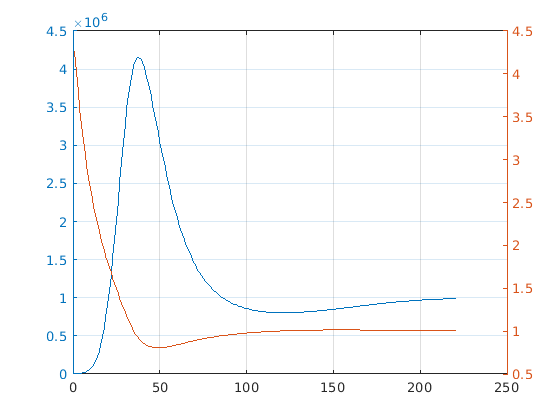

syms S I R
syms beta mu gamma

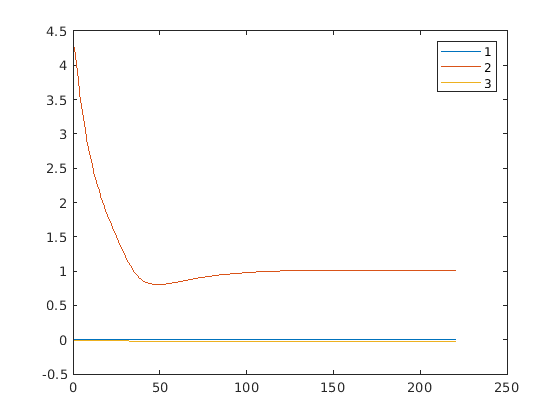


q1 = S*(1-I*beta/N);
q2 = S*beta*I/N +(1-gamma)*I;
q3 = gamma*I;



jacobian([q2 q1 q3], [I S R])
X = [S*beta/N]/[1-[1-gamma]]
eig(X)